- Non-drift case 

Consider 


$$z_k = x_k + v_k , x_0 \sim N(x_0, M)$$


clear all;clf 
rng('default')
n = 100;    % number of sampling 
t = linspace(0,10,n);
mX = 2; varX = 2;      
mV = 0; varV = 1;   

barX = mX; M=  varX;
barV = mV; V = varV;

% Initialization - case 1) known initial value
% estX(1) = mX;  P = varX;

% Initialization - case 2) unknown initial value
% guess the initial point 

estX(1) = 0;  P = 1;
for i = 1:n
        
    K = inv(inv(P) + inv(V))*V;
    P= inv(inv(P) + inv(V));
    
    x(i) = barX + sqrt(M)*randn(1,1);
    v(i) = barV + sqrt(V)*randn(1,1);    
    z(i) = x(i) + v(i);
    
    estX(i+1) = estX(i) + K*(z(i)-estX(i));

end 

figure(1)
plot(t,z); hold on;  grid on
plot(t,estX(1:end-1), 'linewidth',2,'color','r'); 

 The best estimator $\hat {x} $ (estX  in the code) in MV sense converges to the mean of the real x ( = mX in the code) . Here the initial value of the real state is the **"Known**" . However in general the initial value is unknown. Then we may estimate or guess the initla point. In general 

 
$$\bar{x_0 } = 0, M = Identity \ matrix$$


In this case, still the estimator converges to the real $x$.

-  Ex.3.10 : Single-axis Satellite Attitude Detemination;

 1. Objectives

    -How well it converges to the true state;

    -Analyze the satellite  antenna system parameter, noise above 1/(5*sampleing time)

 2. Model 


$$ \left[ \matrix { \theta_{k+1} \cr  \dot{\theta}_{k+1}}  \right ] = \left[ \matrix{1  & T \cr 0 & 1 } \right] \left[ \matrix { \theta_{k} \cr  \dot{\theta}_{k}}  \right ] + \left[ \matrix{T^2/2  \cr T }\right]u_k +  \left[ \matrix{T^2/2  \cr T }\right]w_k  $$



$$z_k = \left [ \matrix {1  & 0 }\right] \left[ \matrix {\theta _k \cr  \dot{\theta}_{k} }\right] + v_k $$


  For predictor 


$$ \left[ \matrix { \bar{\theta}_{k+1} \cr \bar \dot{ \theta} _{k+1} }  \right ] = \left[ \matrix {0 & T \cr 0 & 1 }\right]  \left[ \matrix { \bar{\theta}_{k} \cr \bar{ \dot\theta} _{k} }  \right ] $$


 For estimator 


$$ \left[ \matrix { \hat{\theta}_{k+1} \cr \hat\dot{ \theta} _{k+1} }  \right ] = \left[ \matrix {1 & T \cr 0 & 1 }\right]  \left[ \matrix { \bar{\theta}_{k} \cr \bar{ \dot\theta} _{k} }  \right ] + \left[ \matrix{k_1 \cr  k_2  } \right ] \left[z_k - \bar\theta_k \right]$$


With initial point.

  
$$x_0  = [ 0.01 -0.001]^T, \ M =\left[ \matrix{ 10 &0 \cr 0 & 10} \right]$$


 Simulate uisng kalman Filter, 

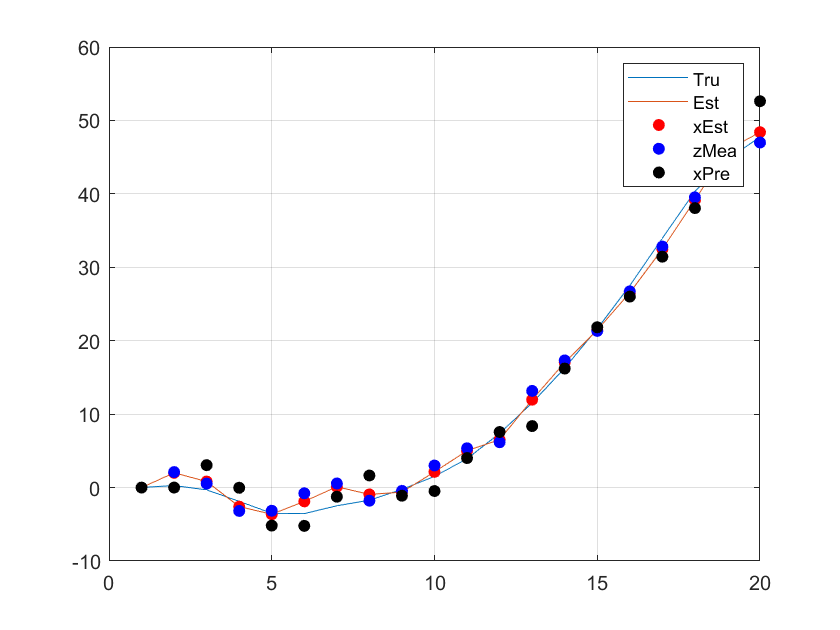

% Define System Parameter 
T =1;    % sampling time
rng('default')
Phi =[ 1 T;  0 1]; G = [T^2/2  ; T]; H = [1 0]; W=1; V =1;
N=20;  % numbe of sampling

% Initial value for the system
xTrue(:,1) = [0.01 ; -0.001];   % initial state
M =[10 0; 0 10];                % initial state  cov 

% Initail value for the Kalman filter
xEst(:,1) = [ 0 ; 0];          % initial estimate state  
P = M;                         % initial estimate variance 


for i = 1:N-1
 
  % Prediction: between measurements
    xPre(:,i+1)=Phi*xEst(:,i);
    M = Phi*P*Phi' + G*W*G';   % state cov at time

 % system dynamics 
    xTrue(:,i+1) = Phi*xTrue(:,i) + G*randn(1,1);
    
 % Measurement with noise
    zMea(:,i+1) = H*xTrue(:,i+1) + sqrt(V)*randn(1,1);     
    
 % Estimation    

    P = inv( (inv(M) + H'*inv(V)*H));   
%     K(:,i) = P*H'*inv(V)
%     xEst(:,i+1) = xPre(:,i+1) + K(:,i)*(zMea(:,i+1) - H*xPre(:,i+1));
   
    K = P*H'*inv(V);
    xEst(:,i+1) = xPre(:,i+1) + K*(zMea(:,i+1) - H*xPre(:,i+1));
end

figure(1)
plot(1:N, xTrue(1,:), 1:N, xEst(1,:)) ; grid on;hold on
scatter(1:N, xEst(1,:),'filled','red'); 
scatter(1:N, zMea(1,:),'filled','blue'); 
scatter(1:N, xPre(1,:),'filled','black'); 
legend('Tru', 'Est','xEst','zMea','xPre')
hold off

 Here Kalman filter gain is to be constant after t = 7 step. If the variance is changed, the time step for the gain to be constant is varying. Check it. 